%Importing all data
rawdata = xlsread('HW.xlsx')

rawdata =         1350          79         393         161         870         165
        1588          85         468         177        1110         160
        1294          68         424         168        1050         152
        1222          59         412         161         930         151
        1585          98         439         164        1105         165
        1297          82         429         169        1080         160
        1796          79         449         169        1160         154
        1565          55         424         163        1010         140
        2664         128         452         173        1320         180
        1166          55         399         157         815         140


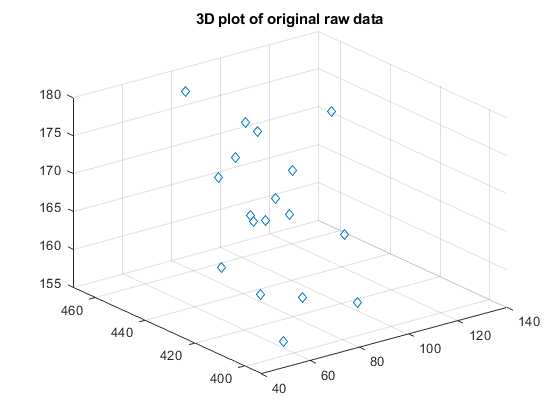

%Scatter Plot of raw data
scatter3(rawdata(:,2),rawdata(:,3),rawdata(:,4),'diamond');
title("3D plot of original raw data");

%Adjusted data
size_raw = size(rawdata);
row = size_raw(1,1);
col = size_raw(1,2);
adjustData = zeros(row, 3);
mean_x2 = mean(rawdata(:,2));
mean_x3 = mean(rawdata(:,3));
mean_x4 = mean(rawdata(:,4));
adjustData(:,1) = rawdata(:,2) - mean_x2;
adjustData(:,2) = rawdata(:,3) - mean_x3;
adjustData(:,3) = rawdata(:,4) - mean_x4;
adjustData

adjustData =    -5.6111  -40.5000   -5.6667
    0.3889   34.5000   10.3333
  -16.6111   -9.5000    1.3333
  -25.6111  -21.5000   -5.6667
   13.3889    5.5000   -2.6667
   -2.6111   -4.5000    2.3333
   -5.6111   15.5000    2.3333
  -29.6111   -9.5000   -3.6667
   43.3889   18.5000    6.3333
  -29.6111  -34.5000   -9.6667


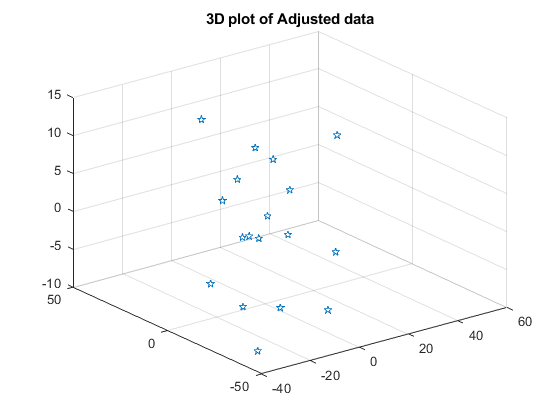

%Scatter Plot of Adjusted data
scatter3(adjustData(:,1),adjustData(:,2),adjustData(:,3),'pentagram');
title("3D plot of Adjusted data");

%Calculating covariance matrix
cov_x = cov(adjustData)

cov_x =   415.1928  288.9118   56.3922
  288.9118  488.7353   99.7647
   56.3922   99.7647   28.2353


%Calculating eigen vector and eigen value
[eig_vector, eig_value] = eig(cov_x)

eig_vector =     0.0146   -0.7608   -0.6488
   -0.2114    0.6319   -0.7457
    0.9773    0.1480   -0.1516


eig_value =     7.5007         0         0
         0  164.2593         0
         0         0  760.4034


diag_eig = diag(eig_value)

diag_eig =     7.5007
  164.2593
  760.4034


%Calculating Principle Component
e1 = diag_eig(1) %first eigen value

e1 = 7.5007

e2 = diag_eig(2) %second eigen value

e2 = 164.2593

e3 = diag_eig(3) %third eigen value

e3 = 760.4034

pvar1 = (e1/(e1+e2+e3))*100 %percentage variance of e1

pvar1 = 0.8047

pvar2 = (e2/(e1+e2+e3))*100 %percentage variance of e2

pvar2 = 17.6213

pvar3 = (e3/(e1+e2+e3))*100 %percentage variance of e3

pvar3 = 81.5740

%Note:We know eigen vector with the highest eigen value is considered as
%the principal component of data set. Here, eigen vector with the largest
%eigen value was the third column. Also taking into account the second
%column of eigen vector as its eigen value is significant
feature_vector = [eig_vector(:,3), eig_vector(:,2)]

feature_vector =    -0.6488   -0.7608
   -0.7457    0.6319
   -0.1516    0.1480


%Now we obtain the final data
final_data = adjustData * feature_vector

final_data =    34.6997  -22.1614
  -27.5446   23.0340
   17.6597    6.8320
   33.5084    5.0602
  -12.3842   -7.1055
    4.6961   -0.5115
   -8.2711   14.4086
   26.8524   15.9821
  -42.9072  -20.3824
   46.4039   -0.7033


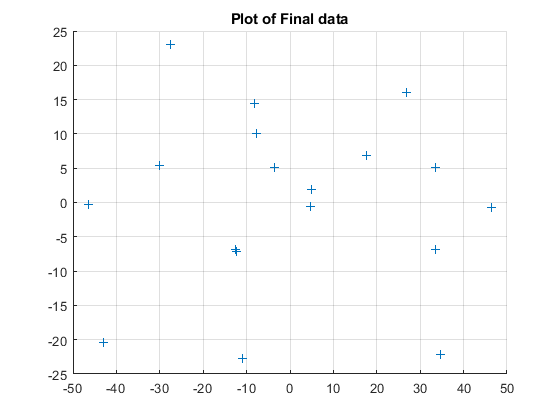


%Scatter Plot of Final data
scatter(final_data(:,1),final_data(:,2),'+');
title("Plot of Final data");
grid on;

%Decoding data
decodedInput = (final_data * feature_vector');
decodedInput(:,1) = decodedInput(:,1) + mean_x2;
decodedInput(:,2) = decodedInput(:,2) + mean_x3;
decodedInput(:,3) = decodedInput(:,3) + mean_x4;
decodedInput

decodedInput =    78.9570  393.6216  158.1261
   84.9589  468.5944  174.2519
   67.9552  424.6486  165.0013
   59.0200  411.7109  162.3366
   98.0522  438.2447  167.4919
   81.9533  429.6750  165.8791
   79.0158  448.7721  170.0535
   55.0293  423.5756  164.9624
  127.9574  452.6158  170.1531
   55.0378  398.4531  159.5287


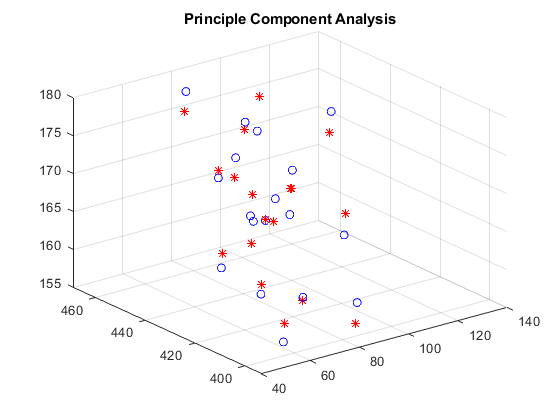

%Plot showcasing Principle Component Analysis
figure;
scatter3(rawdata(:,2),rawdata(:,3),rawdata(:,4),'blue','o');
hold on;
scatter3(decodedInput(:,1),decodedInput(:,2),decodedInput(:,3),'red','*');
grid on;
title("3D - Principle Component Analysis");

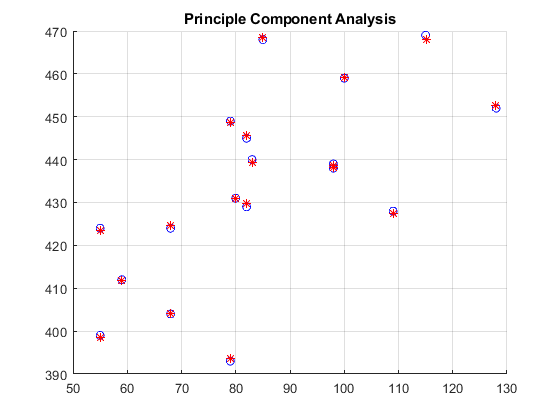

%2DPlot showcasing Principle Component Analysis
figure;
scatter(rawdata(:,2),rawdata(:,3),'blue','o');
hold on;
scatter(decodedInput(:,1),decodedInput(:,2),'red','*');
grid on;
title("2D - Principle Component Analysis");